## Init workspace

Run the following cell to clear all the variables and close all the tabs.

clear all
close all

## Plant of the SS

In this section we want to implement all the variables of the space state.

### Physical values definition

g = 9.8;            %Gravity acceleration
m_B = 0.064;        %Ball mass
m_b = 0.65;         %Beam mass
R = 0.0254;         %Ball radius
L = 0.425;          %Beam Length
d = 0.12;           %Lever length
delta_2 = 0.2;      %Equilibrium Point of ball position
K_m = 0.00767;      %Back EMF constant
K_i = 0.00767;      %Torque Constant
K_g = 14;           %Gear ratio
R_m = 2.6;          %Motor resistance
n_motor = 0.69;     %Motor efficiency
n_gearbox = 0.85;   %Gearbox efficiency

n_total = n_motor + n_gearbox;  %Total efficiency
J_b = (1/2)*m_b*L^2;            %Beam moment of inertia 

### Space State - Plant definition

a_32 = ((m_B*J_b*g) + m_B^2*g*delta_2^2)/(J_b+m_B*delta_2^2)^2;
a_33 = ((K_g^2*K_i*K_m*n_total)/(R_m*(J_b+m_B*delta_2^2)))*(L^2/d^2);
a_41 = (5*g/7);

% Define the A matrix for SS
A = [0,     0,      1,    0 ;
     0,     0,      0,    1 ;
     0,     -a_32, -a_33, 0;
     -a_41, 0,      0,    0];
 
b_31 = ((K_g*K_i*n_total)/(R_m*(J_b+m_B*delta_2^2)))*(L/d);

% Define the B matrix for SS
B = [0;
     0;
     b_31;
     0];

% Define the C matrix for SS
C = [0 1 0 0];

% Define the D matrix for SS
D = 0;

% Show the plant space state
PWC = ss(A,B,C,D);
PWC

PWC =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3       0  -10.24  -1.398       0
   x4      -7       0       0       0
 
  B = 
          u1
   x1      0
   x2      0
   x3  3.677
   x4      0
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



### Noise and Disturbances definition

%Output perturbance
OP = 0.1;
%Input perturbance
IP = 0.8;
%parameter uncertainty
S = 1.1;
% Define the system order
n = size(A,1);

### Plant Without Control

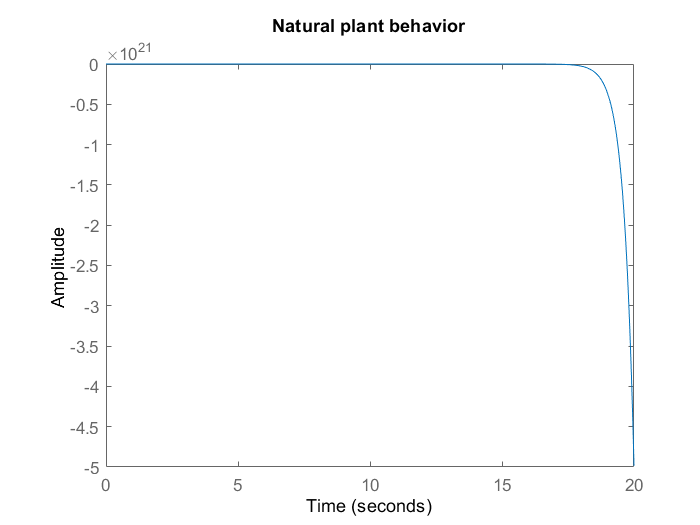

step(PWC,20), title('Natural plant behavior')

disp('As can be seen, it is initially an unstable system.')

As can be seen, it is initially an unstable system.


## Controllability

controllable = rank(ctrb(A,B));
if controllable == n
    resp_controllability = 'Controllable';
else
    resp_controllability = 'Uncontrollable';
end
disp(['The system is: ',resp_controllability]);

The system is: Controllable


## Obserbability

observable = rank(obsv(A,C));
if observable == n
    resp_observability = 'Observable';
else
    resp_observability = 'Unobservable';
end
disp(['The system is: ',resp_observability]);

The system is: Observable


## Control Design And Static Error

Design control for OS=4% and Ts=0.7

### Eigenvalue Placement

To modify the plant dynamics according to the desired parameters, the eigenvalue positioning technique will be used.

% Desired plant dynamics parameters
OS=4;
Ts=0.7;

Considering the standard second-order transfer function


$$G\left(s\right)=\frac{\omega {\;}_n^2 }{s^2 +2\xi \omega_n +\omega_n }$$


From which the eigenvalues are


$$\lambda_{1,2} =-\xi \omega_n \pm \omega_n \sqrt{\xi^2 -1}$$


Now, given a percentage of overshoot and a setting time of the step response we can obtain the damping ratio and undamped natural frecuency with the following equation.


$$\xi^{\prime } =\frac{\left|\ln \left(\frac{\textrm{OS}\;}{100}\right)\right|}{\sqrt{\pi {\;}^2 \;+{\left\lbrack \ln \left(\frac{\textrm{OS}\;}{100}\right)\right\rbrack }^{2\;} }}$$



$${\omega_n }^{\prime } =\frac{\;4}{\xi^{\prime } \;t_s }$$


The code implementation is the following.

% Define the dominant poles
E = abs(log(OS/100))/sqrt(pi^2+(log(OS/100))^2);
Wn = 4/(E*Ts);

polescl1_PUC1 = -E*Wn+Wn*sqrt(E^2-1);
polescl2_PUC1 = -E*Wn-Wn*sqrt(E^2-1);
polescl3_PUC1 = real(polescl1_PUC1)*10;
polescl4_PUC1 = polescl3_PUC1-1;
Polescl_PUC1 = [polescl1_PUC1 polescl2_PUC1 polescl3_PUC1 polescl4_PUC1];

% Place the poles to shape the system dynamic
K1 = place(A,B,Polescl_PUC1);

### Static Error Control

When we use a feedback state control to modify the system behavior, we don't guarantee null static error, which can be briefly defined as the difference between the measured value and the true value of the quantity. 

We can implement a pre-compensation gain to reduce this error. One of the major advantages of implementing this method is that we don't need to increase the system order to control the error, but on the other hand, it may not work in all cases and may even increase the static error.

% Determine the precompensation gain
Kpre1 = inv(-(C-D*K1)*inv(A-B*K1)*B + D);

When we do not know exactly the parameterization of the system states. In order to eliminate the static error, it's necessary to increase the orden of the system. This is possible by adding to the plant an additional integral part.

% Define the extended Space State
Aext = [A zeros(n,1) ; -C 0];
Bext = [B ; -D];
Cext = [C 0];
Dext = 0;

% Poles placement for extended SS
polescl5_PUC1 = polescl4_PUC1-1;
Polescl_PUC1_ext = [polescl1_PUC1 polescl2_PUC1 polescl3_PUC1 polescl4_PUC1 polescl5_PUC1];
Kext1 = place(Aext,Bext,Polescl_PUC1_ext);
K1ext = Kext1(1:n);
Kpre1ext = Kext1(n+1);

### Plant Under Control - Eigenvalue placement - Static Error

Acl1 = A-B*K1;
PUC1 = ss(Acl1,B,C,D);
PUC1

PUC1 =
 
  A = 
              x1         x2         x3         x4
   x1          0          0          1          0
   x2          0          0          0          1
   x3      -4704  3.026e+04     -126.7       6474
   x4         -7          0          0          0
 
  B = 
          u1
   x1      0
   x2      0
   x3  3.677
   x4      0
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



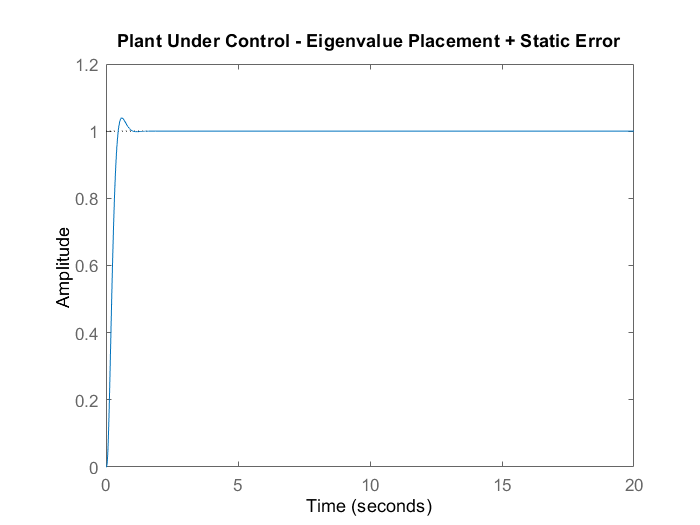

step(Kpre1*PUC1,20), title('Plant Under Control - Eigenvalue Placement + Static Error')

stepinfo(Kpre1*PUC1)

ans = struct with fields:
        RiseTime: 0.2782
    SettlingTime: 0.7788
     SettlingMin: 0.9017
     SettlingMax: 1.0391
       Overshoot: 3.9133
      Undershoot: 0
            Peak: 1.0391
        PeakTime: 0.6020


disp('As can be seen, we have managed to get pretty close to the desired dynamics of the system and to remove the Static Error on the system response.')

As can be seen, we have managed to get pretty close to the desired dynamics of the system and to remove the Static Error on the system response.


## ITAE Control

The ITAE (Integral of Time multiplying the Absolute value of Error) method tries to shape the system dynamic by penalizing the error, in our case, the deviation between the unit step response and the steady-state value.


$$\textrm{ITAE}=\int_0^{\infty \;} t\left|e\left(t\right)\right|\textrm{dt}$$


Minimizing the ITAE objective function yields a step response with relatively small overshoot and relatively little osillation.

For a Fourth order system we have the following characteristic polynominal.


$${G\left(s\right)\;=\;s}^4 +2\ldotp 1{\omega {\;}_n s}^{3\;} +3\ldotp 4\omega_n^{2\;} s^2 +2\ldotp 7\omega_{n\;}^3 s+\omega_n^4$$


Now we must specify the desired natural frecuency to shape the system dynamics.

Polescl_PUC2 = (roots([1 2.1*Wn 3.4*Wn^2 2.7*Wn^3 Wn^4]))';
K2 = place(A,B,Polescl_PUC2);

### Static Error Control

The extended plant will remain the same as the one calculated for the implementation with the previous technique, what will change will be the poles placement.

% Determine the precompensation gain
Kpre2 = inv(-(C-D*K2)*inv(A-B*K2)*B + D);
% Poles placement
polescl5_PUC2 = real(Polescl_PUC2(4))-1;
Polescl_PUC2_ext = [Polescl_PUC2(1), Polescl_PUC2(2), Polescl_PUC2(3), Polescl_PUC2(4), polescl5_PUC2];
Kext2 = place(Aext,Bext,Polescl_PUC2_ext);
K2ext = Kext2(1:n);
Kpre2ext = Kext2(n+1);

### Plant Under Control - ITAE + Static Error

Acl2 = A-B*K2;
PUC2 = ss(Acl2,B,C,D);
PUC2

PUC2 =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3  -216.8   580.7  -16.77   196.4
   x4      -7       0       0       0
 
  B = 
          u1
   x1      0
   x2      0
   x3  3.677
   x4      0
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



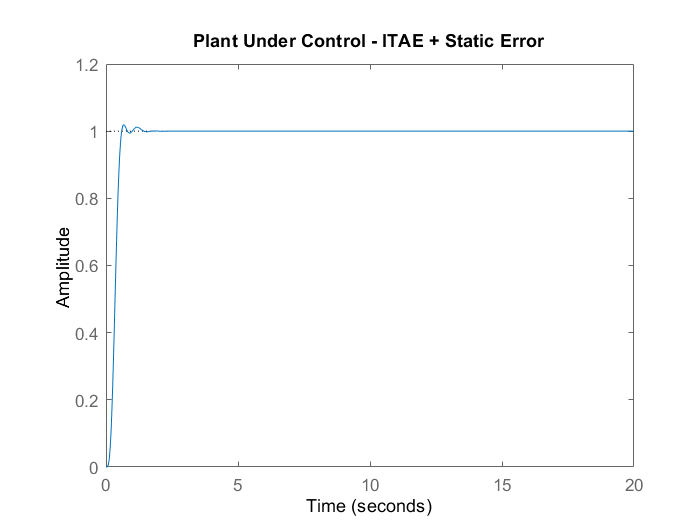

step(Kpre2*PUC2,20), title('Plant Under Control - ITAE + Static Error')

stepinfo(Kpre2*PUC2)

ans = struct with fields:
        RiseTime: 0.3129
    SettlingTime: 0.5651
     SettlingMin: 0.9042
     SettlingMax: 1.0192
       Overshoot: 1.9196
      Undershoot: 0
            Peak: 1.0192
        PeakTime: 0.6665


disp('As can be seen, we have managed to shape the dynamics of the system for almost no overshoot and a fairly short settling time, at the same time removing the static error.')

As can be seen, we have managed to shape the dynamics of the system for almost no overshoot and a fairly short settling time, at the same time removing the static error.


## LQR Control

The theory of optimal control is concerned with operating a dynamic system at minimum cost. The case where the system dynamics are described by a set of linear differential equations and the cost is described by a quadratic function is called the LQ problem.


$$J=\int_0^{\infty \;} \left(x^T \textrm{Qx}+u^T \textrm{Ru}\right)\textrm{dt}$$


where **Q** is the real symmetric or positive definite hermitic matrix and **R** is a real symmetric or positive definite hermitic matrix. The matrices Q and R determine the relative importance of the error and the cost of this energy.

- The weight matrix **Q** is related to performance.

- the weight matrix **R** is related to the effort.

The weight matrix Q will directly affect the system dynamics, i.e. the system states. On the other hand, the weight matrix R will directly affect the system actuators.


$$\left\lbrack \begin{array}{cccc}
x_1  & x_2  & x_3  & x_4 
\end{array}\right\rbrack \left\lbrack \begin{array}{cccc}
Q_1  & 0 & 0 & 0\\
0 & Q_2  & 0 & 0\\
0 & 0 & Q_3  & 0\\
0 & 0 & 0 & Q_4 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_3 
\end{array}\right\rbrack$$
                 
$$u_1 \;R\;\;u_1$$


Q =  [10     0     0    0; % Penalize the beam inclination angle
      0     1     0    0; % Penalize the ball position
      0     0     10    0; % Penalize the beam inclination angular rate
      0     0     0    1]; % Penalize the ball velocity

R = 1.2; % Penalize actuator effort

[K3, S, e] = lqr(A,B,Q,R);

### Static Error

For the LQR case it will be enough to find the pre-compensation gain to deal with the static error.

% Determine the precompensation gain
Kpre3 = inv(-(C-D*K3)*inv(A-B*K3)*B + D);

### Plant Under Control - LQR

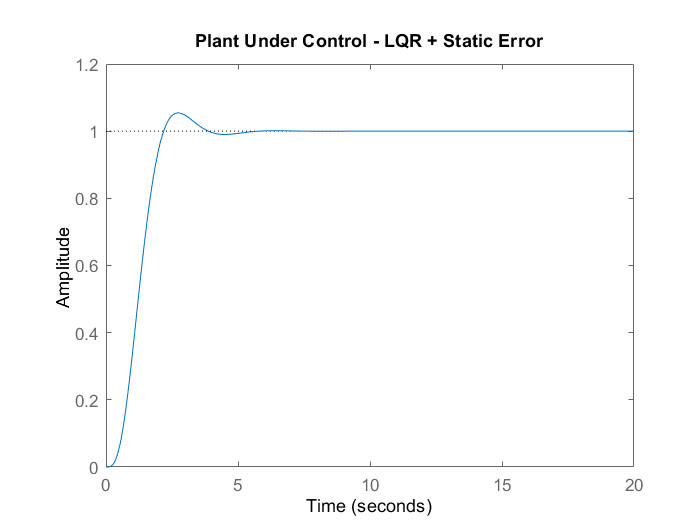

Acl3 = (A-B*K3);
PUC3 = ss(Acl3,B,C,D);

step(PUC3*Kpre3,20), title('Plant Under Control - LQR + Static Error')

stepinfo(Kpre3*PUC2)

ans = struct with fields:
        RiseTime: 0.3129
    SettlingTime: 0.5651
     SettlingMin: 0.0168
     SettlingMax: 0.0189
       Overshoot: 1.9196
      Undershoot: 0
            Peak: 0.0189
        PeakTime: 0.6665


disp('As can be seen, we have managed to control the plant with quite good dynamics, and we have also mitigated the static error.')

As can be seen, we have managed to control the plant with quite good dynamics, and we have also mitigated the static error.


## Space State Observers Design - Eigenvalue Placement

% Define the observer poles 10 times the placed poles
PolesObs1 = Polescl_PUC1(1:n)*10;
% Find the L-values
L1 = place(A',C', PolesObs1)';
% Define the Observer Space State
Aobs1 = A - L1*C;
Bobs1 = [B-L1*D L1];
Cobs1 = eye(n);
Dobs1 = zeros(n,2);

### Observer + States Controller Design

Aoc1 = A-L1*C-B*K1+L1*D*K1;
Boc1 = [B-L1*D, L1];
Coc1 = -K1;
Doc1 = [1, 0];

### Observer + States Controller Design + Static Error

Aocc1 = [A-L1*C-B*K1ext+L1*D*K1ext -B*Kpre1ext+L1*D*Kpre1ext; zeros(1,n) 0];
Bocc1 = [zeros(n,1), L1; 1, -1];
Cocc1 = [-K1ext -Kpre1ext];
Docc1 = zeros(1,2);

## Space State Observers Design - ITAE

% Define the observer poles 10 times the placed poles
PolesObs2 = Polescl_PUC2(1:n)*10;
% Find the L-values
L2 = place(A',C', PolesObs2)';
% Define the Observer Space State
Aobs2 = A - L2*C;
Bobs2 = [B-L2*D L2];
Cobs2 = eye(n);
Dobs2 = zeros(n,2);

### Observer + States Controller Design

Aoc2 = A-L2*C-B*K2+L2*D*K2;
Boc2 = [B-L2*D, L2];
Coc2 = -K2;
Doc2 = [1, 0];

### Observer + States Controller Design + Static Error

Aocc2 = [A-L2*C-B*K2ext+L2*D*K2ext -B*Kpre2ext+L2*D*Kpre2ext; zeros(1,n) 0];
Bocc2 = [zeros(n,1), L2; 1, -1];
Cocc2 = [-K2ext -Kpre2ext];
Docc2 = zeros(1,2);